# Example: Wave Module

The following example runs an application of the wave module to: generate a capture length matrix, calculate MAEP, and plot the scatter diagrams.

## Getting Started Calculating Wave Resource Characteristics 

Now we will generate a few matrices for example data. In a real application, the user would provide these values, or they cold be computed from the wave.resource module. 

% generating an array of 1,000,000 values to represent significant wave
% height
Hm0 = normrnd(5.5,1.3,1000000,1);

Hm0 =    4.520857946074420
   7.113006633504239
   8.900616594696086
   5.453020533841783
   3.958874830234092
   6.399278744164349
   6.245174326572077
   6.411570353465944
   5.768395869323923
   5.043391788349245


% generating 1,000,000 values for peak period, assumng normal distribution
Te = normrnd(4.5,0.7,1000000,1);

## Generating Basic Capture Length Matrices

Now we will generate a few matrices for example data. In a real application, the user would provide these values. 

% generating 1,000,000 random power values
Power = randi([40,200], 1000000,1); 

% generating 1,000,000 random omnidirectional wave flux values
J = randi([8,300], 1000000,1);

Soon, we can create our capture length matrices, as specified by the IEC/TS 62600-100. But first, we need to calculate our capture lengths and generate our bin values as an array indicate the centers of each bin.

The following operations are how you generate the five matrices specified by the IEC/TS 62600-100. We also generate a frequency matrix for convenience.

L = capture_length(Power,J); % calculating capture length with power and wave flux in vectors

% Need to set our Hm0 and Te bins for the capture length matrix
Hm0_bins = -0.5:0.5:max(fix(Hm0))+0.5; % Input is min, max, and n indecies for vector
Hm0_bins = Hm0_bins+0.25 ; 
Te_bins = 0:1:max(fix(Te));
Te_bins = Te_bins+0.5;

% Calculate the necessary capture length matrices for each statistic based
% on IEC/TS 62600-100
clmat.mean = capture_length_matrix(Hm0,Te,L,"mean",Hm0_bins,Te_bins);
clmat.std = capture_length_matrix(Hm0,Te,L,"std",Hm0_bins,Te_bins);
clmat.count = capture_length_matrix(Hm0,Te,L,"count",Hm0_bins,Te_bins);
clmat.min = capture_length_matrix(Hm0,Te,L,"min",Hm0_bins,Te_bins);
clmat.max = capture_length_matrix(Hm0,Te,L,"max",Hm0_bins,Te_bins);

% Calculate the frequency matrix for convenience 
clmat.freq = capture_length_matrix(Hm0,Te,L,"frequency",Hm0_bins,Te_bins);

Let's see what the data in the mean matrix looks like. Keep in mind that this data has been artificially generated, so it may not be representative of what a real-world scatter diagram would look like.

disp(clmat.mean.values)

  Columns 1 through 7

                 NaN                 NaN   0.430555555555556   0.663888888888889   2.158029131468014   1.450291962830401                 NaN
                 NaN                 NaN   2.034584980237154   0.684380887675285   1.731182329209120   0.934058212117620                 NaN
                 NaN                 NaN  10.112162162162161   1.171608985249496   1.653136710082748   1.249513307576036   0.654886437632994
                 NaN                 NaN   0.896524418727282   1.601371447236241   1.657151188373887   1.514063790242400   1.625069528779115
                 NaN                 NaN   1.555126314416134   1.507621770639513   1.378011930536380   1.534721893034648   1.591291070203502
                 NaN                 NaN   1.500008758008421   1.549004299447762   1.460992062374245   1.469906962632314   1.593049491338693
                 NaN   1.582553707553708   1.360168773267239   1.530835261991911   1.433500499480601   1.548711676021159   1.613235

## Power Matrices

The IEC/TS 62600-100 specifies that the power matrix should be generated from the capture length matrix. The following is an example of how to do that. To generate the power matrix, you need to have a matrix of the wave energy flux, so we calculate one, then we generate the power matrices.

jmat = wave_energy_flux_matrix(Hm0,Te,J,"mean",Hm0_bins,Te_bins);

avg_power_mat = power_matrix(clmat.mean, jmat);
std_power_mat = power_matrix(clmat.std, jmat);

The `capture_length_matrix` function can also be used as an arbitrary scatter plot generator. To do this, simply pass a different array in the place of capture length (L). For example, while not specified by the IEC standards, if the user doesn't have the omnidirectional wave flux, the average power matrix could hypothetically be generated in the following manner:

avgpowmat_not_standard = capture_length_matrix(Hm0,Te,Power,'mean',Hm0_bins,Te_bins);

## MAEP

There are two ways to calculate MAEP. One is from a scatter diagram, the other is from time-series data.

maep_timeseries = mean_annual_energy_production_timeseries(L,J)

maep_timeseries =      1.051616503548000e+06



maep_matrix = mean_annual_energy_production_matrix(clmat.mean, jmat , clmat.freq)

maep_matrix =      2.033858316166300e+06


## Graphics

Printing the results of these calculations to standard output can look a little bit messy. Let's try graphing the outputs using the graphics module's `plot_matrix` function. It is important to note that the plotting function expects the step size between bins to be linear.

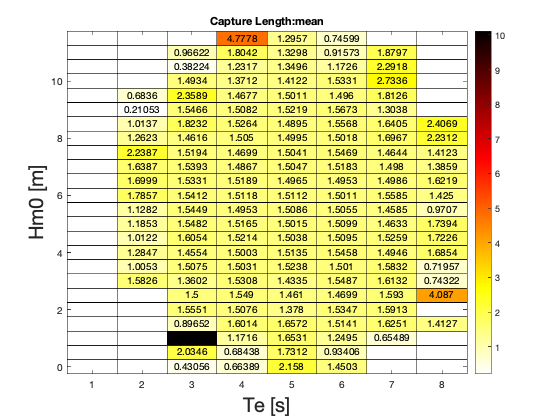

p1 = plot_matrix(clmat.mean,"Capture Length");